## MATLAB code for the VHDL processing of the image

Pre-processing of the data

clear all; close all; format long
for z=1:1
    preprocess_start(z) = cputime;
    I1 = imread('lena_color.jpg');
    figure(1);
    imshow(I1);
    title('Original Image')
    I2 = imresize(I1, [128, 128]);
    figure(2);
    imshow(I2);
    title('Resize Image')
    %To detect if the image needs resizing and grey filter
    [rows columns numberOfColorBands] = size(I1);
    if(numberOfColorBands == 3)
        pre_image = im2gray(I2);
        figure(3);
        imshow(pre_image);
        title('Resize grey Image')
    else 
        pre_image = I2;
    end
    
    hex_pre_image = dec2hex(pre_image);
    fid = fopen('ImageRawArrayHex.txt', 'w');
    
    if fid == -1, error ('Cannot open file'); end
    [rows columns numberOfColorBands] = size(I1);
    %fprintf(fid, 'Size: %d\n', size(pre_image));
    fprintf(fid, '%02X ', pre_image);
    fclose(fid);
    preprocess_end(z) = cputime - preprocess_start(z); %in seconds  

MATLAB code for Edge detection using Laplacian Filter.

    laplacian_start(z) = cputime;
    k1=double(pre_image);
    % Define the Laplacian filter.
    Laplacian=[0 1 0; 1 -4 1; 0 1 0];
    % Convolve the image using Laplacian Filter
    k2=conv2(k1, Laplacian, 'same');
    % Display the image.
    figure;
    imshow(k2);
    title('Edge detection of Lena using Laplacian filter');
    laplacian_end(z) = cputime - laplacian_start(z); % in seconds

MATLAB code for Edge detection using Difference of Gaussian

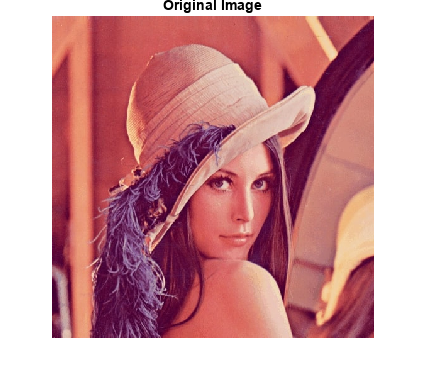

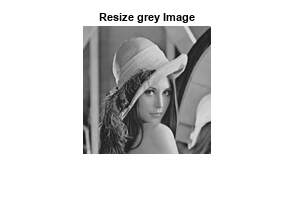

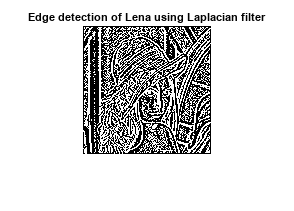

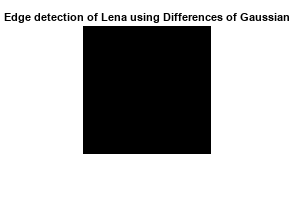

    gaussian_start(z) = cputime;
    k3 = 10;
    sigma1 =  0.5;
    sigma2 = sigma1*k3;
    
    hsize = 5;
    
    gauss1 = fspecial('Gaussian', hsize, sigma1);
    gauss1 = gauss1.*400;
    gauss1 = round(gauss1);
    gauss1_hex = dec2hex(gauss1);
    gauss2 = fspecial('Gaussian', hsize, sigma2);
    
    dogImg = gauss2 - gauss1;
    dogFilterImage = conv2(pre_image, dogImg, 'same');
    
    figure;
    imshow(dogFilterImage);
    title('Edge detection of Lena using Differences of Gaussian');
    gaussian_end(z)= cputime - gaussian_start(z); %in seconds

Post-processing of the data

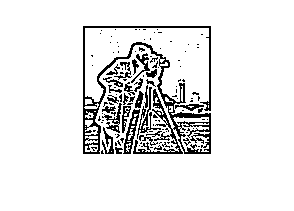

    %Measure time
    postprocess_start(z) = cputime;
    filename = 'OUT.txt';
    FID = fopen(filename);
    dataFromfile = textscan(FID, '%s ');% %s for reading string values (hexadecimal numbers)
    dataFromfile = dataFromfile{1};
    endFile = size(dataFromfile);
    for i=1:(endFile-1)
        newStr(i)=extractBetween(dataFromfile(i),10,13);
    end
    q = quantizer('fixed', 'nearest', 'saturate', [16 0]);% quantizer object for num2hex function  
    decData = hex2num(q, newStr);
    decData1 = cell2mat(decData);
    fclose(FID);
    %Measure time
    postprocess_end(z) = cputime - preprocess_start(z); %in seconds
    outImg = reshape(decData1, [128,128]);
    
    figure;
    imshow(outImg);


end

preprocess_time = mean(preprocess_end)
laplacian_time = mean(laplacian_end)
gaussian_time = mean(gaussian_end)
postprocess_time = mean(postprocess_end)

preprocess_time =    3.171875000000000


laplacian_time =    0.250000000000000


gaussian_time =    0.453125000000000


postprocess_time =   11.390625000000000
